a=1.5;b=0;
x1 = [3.5 1]; x2 = [2.5 -1];x3 = [0.5 -1];x4 = [0.5 1];
fun = @(x,y)(1-x+a)^2 + 100*(y-b-(x-a)^2)^2;
%fsurf(fun,[-1,4],'ShowContours','on')
%xlabel('x');ylabel('y');zlabel('f(x,y)');


 
 Iteration   Func-count     min f(x)         Procedure
     0            1                4         
     1            3                4         initial simplex
     2            5          3.90066         reflect
     3            7          3.90066         contract inside
     4            9          3.85199         expand
     5           11          3.61712         expand
     6           13          3.32791         expand
     7           15          3.16926         reflect
     8           17          2.75258         expand
     9           19          2.75258         contract inside
    10           21          2.55687         reflect
    11           23          2.55687         contract inside
    12           24          2.55687         reflect
    13           26           2.3988         reflect
    14           28           2.3988         contract inside
    15           30          2.29161         expand
    16           32          2.05546         expand
    17         

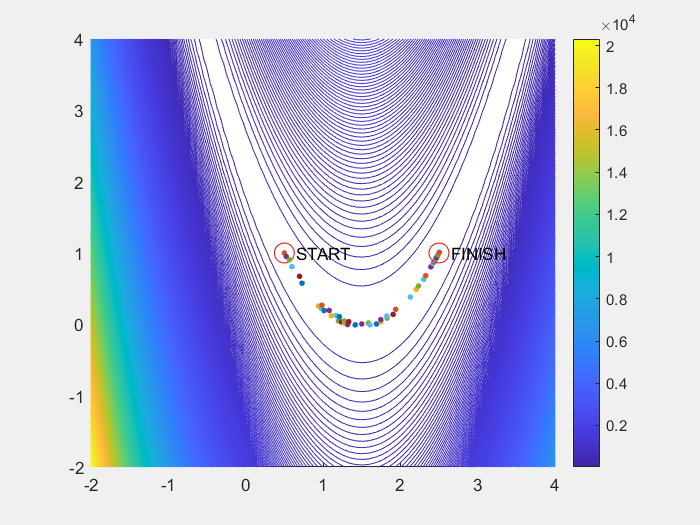

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



% Pass fixed parameters to objfun
objfun = @(optimInput)objectiveFcn(optimInput,a,b);

% Set nondefault solver options
options = optimset("Display","iter","PlotFcn",@out);
%options = optimset("Display","iter","PlotFcn","optimplotlogfval");

% Solve
[solution,objectiveValue,exitflag,output] = fminsearch(objfun,x4,options);


% Clear variables
clearvars objfun options

disp('Minimum funkcji:');disp(solution)

Minimum funkcji:
    2.5000    1.0000



disp('Wartość funkcji w minimum:');disp(objectiveValue)

Wartość funkcji w minimum:
   6.5465e-10



disp('Liczba iteracji');disp(output.iterations)

Liczba iteracji
    99



disp('Liczba wywołań funkcji celu');disp(output.funcCount)

Liczba wywołań funkcji celu
   188



function f = objectiveFcn(optimInput,a,b)
x = optimInput(1);
y = optimInput(2);
f = (1-x+a)^2 + 100*(y-b-(x-a)^2)^2;
end